% State and state derivatives
syms X_dot u_dot Y_dot v_dot psi_dot r_dot X u Y v psi r 
% Inputs
syms delta_f F_x

%constants
Nw=2;
f=0.01;
Iz=2667;
a=1.35;
b=1.45;
By=0.27;
Cy=1.2;
Dy=0.7;
Ey=-1.6;
Shy=0;
Svy=0;
m=1400;
g=9.806;


%slip angle functions in degrees
a_f=rad2deg(delta_f-atan2(v+a*r,u));
a_r=rad2deg(-atan2((v-b*r),u));

%Nonlinear Tire Dynamics
phi_yf=(1-Ey)*(a_f+Shy)+(Ey/By)*atan(By*(a_f+Shy));
phi_yr=(1-Ey)*(a_r+Shy)+(Ey/By)*atan(By*(a_r+Shy));

F_zf=b/(a+b)*m*g;
F_yf=F_zf*Dy*sin(Cy*atan(By*phi_yf))+Svy;

F_zr=a/(a+b)*m*g;
F_yr=F_zr*Dy*sin(Cy*atan(By*phi_yr))+Svy;

F_total=sqrt((Nw*F_x)^2+(F_yr^2));
F_max=0.7*m*g;
% 
% if F_total>F_max
% 
%     F_x=F_max/F_total*F_x;
% 
%     F_yr=F_max/F_total*F_yr;
% end

%vehicle dynamics
dzdt= [u*cos(psi)-v*sin(psi);...
          (-f*m*g+Nw*F_x-F_yf*sin(delta_f))/m+v*r;...
          u*sin(psi)+v*cos(psi);...
          (F_yf*cos(delta_f)+F_yr)/m-u*r;...
          r;...
          (F_yf*a*cos(delta_f)-F_yr*b)/Iz];

J_z = jacobian(dzdt,[X u Y v psi r]);
J_u = jacobian(dzdt,[delta_f F_x]);

%Operating points
% X = 0;
% u = 17.88; %17.88 m/s = 40 mph
% Y = 0;
% v = 0;
% psi = 0;
% r = 0;
% delta_f = 0;
% F_x = 66.7;

% Turning
X = 0;
u = 7.6;
Y = 0;
v = 0.6;
psi = 0;
r = 0.26;
delta_f = 0.2;
F_x = 225;

A = double(subs(J_z));
B = double(subs(J_u));
double(subs(dzdt))

ans =     7.6000
   -0.2870
    0.6000
   -0.4318
    0.2600
    3.6563


real(jordan(A))

ans =          0    1.0000         0         0         0         0
         0         0         0         0         0         0
         0         0   -0.0241         0         0         0
         0         0         0  -10.4307         0         0
         0         0         0         0   -7.1016         0
         0         0         0         0         0         0


% % dz_zt_lin = A*(z-z_op) + B*(u-u_op) + subs(dzdt)
% [eigvec, lambda] = eig(A);
% disp(real(lambda))

C = eye(6);
D = zeros(6,2);

t = 0:0.01:10;
Fx = 0*ones(size(t));
deltaf = 0*t;
u = [deltaf; Fx];
dx0 = zeros(1,6);
dx0(2) = 17.88;
system = ss(A,B,C,D)

system =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         1         0         0      -0.6         0
   x2         0  -0.03614         0    0.5488         0    0.9899
   x3         0         0         0         1       7.6         0
   x4         0    0.1238         0    -8.428         0    0.6312
   x5         0         0         0         0         0         1
   x6         0  -0.03007         0     4.321         0    -9.092
 
  B = 
             u1        u2
   x1         0         0
   x2    -5.517  0.001429
   x3         0         0
   x4     10.33         0
   x5         0         0
   x6     7.321         0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
   y5   0   0
   y6   0   0
 
C

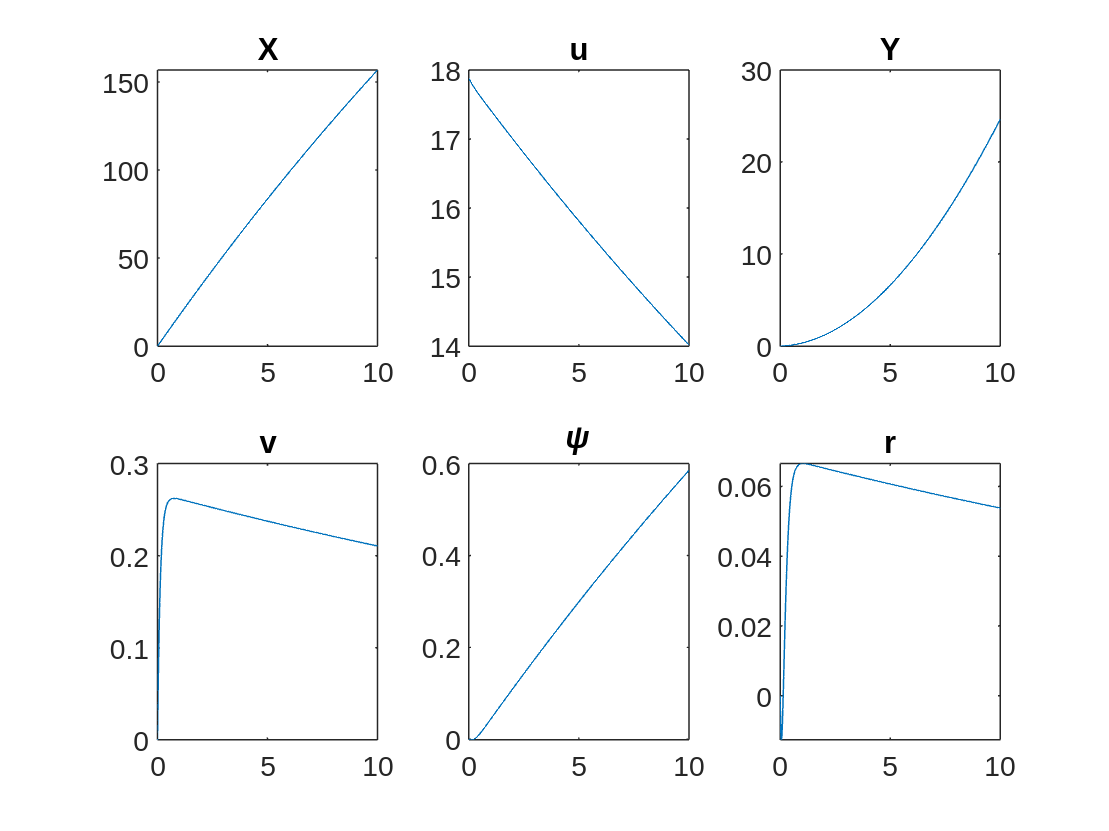

[ylin, t] = lsim(system, u, t, dx0);

labels = ["X", "u", "Y", "v", "\psi", "r"];
figure;
for i = 1:6
    subplot(2,3,i)
    plot(t, ylin(:,i))
    title(labels(i))
end